
syms alpha1(t) alpha2(t) alpha3(t) alpha4(t) alpha5(t)  T_b A
syms w1(t) w2(t) w3(t) w4(t) w5(t) 
syms beta1(t) beta2(t) beta3(t) beta4(t) beta5(t) 
assume(T_b>0)
assume(A>0)
anguloInicialB=-6*pi/180;
anguloFinalB=6*pi/180;
A=2; %rad s^-2
alpha1(t)=10*A/T_b*t;
alpha2(t)=A;
alpha3(t)=-10*A/T_b*t;
Calpha3=A-alpha3(4*T_b/10);
alpha3(t)=alpha3(t)+Calpha3;
alpha4(t)=-A;
alpha5(t)=10*A/T_b*t;
Calpha5=alpha4(9*T_b/10)-alpha5(9*T_b/10);
alpha5(t)=alpha5(t)+Calpha5;
fprintf('Función de aceleración angular:')

Función de aceleración angular:

alpha(t)=piecewise((0<=t<T_b/10),alpha1,(T_b/10<=t<4*T_b/10),alpha2,(4*T_b/10<=t<6*T_b/10),alpha3,(6*T_b/10<=t<9*T_b/10),alpha4,(9*T_b/10<=t<=T_b),alpha5)

$$alpha(t) = \left\{ \begin{array}{cl} \frac{20\,t}{T_{b}} & \text{ if }10\,t<T_{b}\wedge 0\leq t\\ 2 & \text{ if }T_{b}\leq 10\,t\wedge 5\,t<2\,T_{b}\\ 10-\frac{20\,t}{T_{b}} & \text{ if }5\,t<3\,T_{b}\wedge 2\,T_{b}\leq 5\,t\\ -2 & \text{ if }10\,t<9\,T_{b}\wedge 3\,T_{b}\leq 5\,t\\ \frac{20\,t}{T_{b}}-20 & \text{ if }t\leq T_{b}\wedge 9\,T_{b}\leq 10\,t \end{array}\right.$$

w1(t)=int(alpha1);

w2(t)=int(alpha2);
Cw2=w1(T_b/10)-w2(T_b/10);
w2(t)=w2(t)+Cw2;

w3(t)=int(alpha3);
Cw3=w2(4*T_b/10)-w3(4*T_b/10);
w3(t)=w3(t)+Cw3;

w4(t)=int(alpha4);
Cw4=w3(6*T_b/10)-w4(6*T_b/10);
w4(t)=w4(t)+Cw4;

w5(t)=int(alpha5);
Cw5=w4(9*T_b/10)-w5(9*T_b/10);
w5(t)=w5(t)+Cw5;
fprintf('Función de velocidad angular:')

Función de velocidad angular:

w(t)=piecewise((0<=t<T_b/10),w1,(T_b/10<=t<4*T_b/10),w2,(4*T_b/10<=t<6*T_b/10),w3,(6*T_b/10<=t<9*T_b/10),w4,(9*T_b/10<=t<=T_b),w5)

$$w(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }10\,t<T_{b}\wedge 0\leq t\\ 2\,t-\frac{T_{b}}{10} & \text{ if }T_{b}\leq 10\,t\wedge 5\,t<2\,T_{b}\\ 10\,t-\frac{17\,T_{b}}{10}-\sigma_{1} & \text{ if }5\,t<3\,T_{b}\wedge 2\,T_{b}\leq 5\,t\\ \frac{19\,T_{b}}{10}-2\,t & \text{ if }10\,t<9\,T_{b}\wedge 3\,T_{b}\leq 5\,t\\ 10\,T_{b}-20\,t+\sigma_{1} & \text{ if }t\leq T_{b}\wedge 9\,T_{b}\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{10\,t^{2}}{T_{b}} \end{array}$$


beta1(t)=int(w1)+anguloInicialB;

beta2(t)=int(w2);
Cbeta2=beta1(T_b/10)-beta2(T_b/10);
beta2(t)=beta2(t)+Cbeta2;

beta3(t)=int(w3);
Cbeta3=beta2(4*T_b/10)-beta3(4*T_b/10);
beta3(t)=beta3(t)+Cbeta3;

beta4(t)=int(w4);
Cbeta4=beta3(6*T_b/10)-beta4(6*T_b/10);
beta4(t)=beta4(t)+Cbeta4;

beta5(t)=int(w5);
Cbeta5=beta4(9*T_b/10)-beta5(9*T_b/10);
beta5(t)=beta5(t)+Cbeta5;

fprintf('Función de desplazamiento angular:')

Función de desplazamiento angular:

Fbeta(t)=piecewise((0<=t<T_b/10),beta1,(T_b/10<=t<4*T_b/10),beta2,(4*T_b/10<=t<6*T_b/10),beta3,(6*T_b/10<=t<9*T_b/10),beta4,(9*T_b/10<=t<=T_b),beta5)

$$Fbeta(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1}-\frac{\pi }{30} & \text{ if }10\,t<T_{b}\wedge 0\leq t\\ \frac{{T_{b}}^{2}}{300}-\frac{t\,\left(T_{b}-10\,t\right)}{10}-\frac{\pi }{30} & \text{ if }T_{b}\leq 10\,t\wedge 5\,t<2\,T_{b}\\ \frac{13\,{T_{b}}^{2}}{60}-\frac{17\,T_{b}\,t}{10}-\frac{\pi }{30}+5\,t^{2}-\sigma_{1} & \text{ if }5\,t<3\,T_{b}\wedge 2\,T_{b}\leq 5\,t\\ -\frac{151\,{T_{b}}^{2}}{300}+\frac{19\,T_{b}\,t}{10}-t^{2}-\frac{\pi }{30} & \text{ if }10\,t<9\,T_{b}\wedge 3\,T_{b}\leq 5\,t\\ 10\,T_{b}\,t-\frac{\pi }{30}-\frac{44\,{T_{b}}^{2}}{15}-10\,t^{2}+\sigma_{1} & \text{ if }t\leq T_{b}\wedge 9\,T_{b}\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{10\,t^{3}}{3\,T_{b}} \end{array}$$

f=0==Fbeta(T_b/2);

tMax_b=solve(f,T_b);
fprintf('Tiempo de ciclo %.3f s',tMax_b)

Tiempo de ciclo 0.724 s

alpha=subs(alpha,T_b,tMax_b);
w=subs(w,T_b,tMax_b);
Fbeta=subs(Fbeta,T_b,tMax_b);

## Gráficas

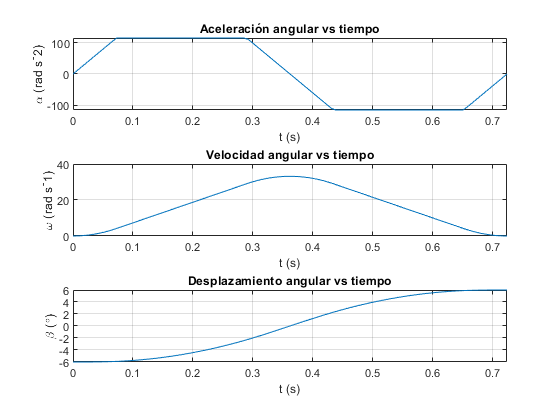

ts=linspace(0,tMax_b,100);
figure()
subplot(3,1,1)
plot(ts,alpha(ts).*180./pi)
title('Aceleración angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\alpha (rad s^-2)')
xlim([0 double(tMax_b)])

subplot(3,1,2)

plot(ts,w(ts).*180./pi)
title('Velocidad angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\omega (rad s^-1)')
xlim([0 double(tMax_b)])

subplot(3,1,3)

plot(ts,Fbeta(ts).*180./pi)
title('Desplazamiento angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\beta (\circ)')
xlim([0 double(tMax_b)])
ylim([-6 6])
yticks(-6:2:6)

clearvars -except tMax_a tMax_c tMax_b Fz_arfada Fbeta Ftheta_c theta1 P_z C_x C_y D_x D_y D_z L_m L_b L_ub L_bm theta_C beta Z_arfada ArfadaCaso1 ArfadaCaso2 ArfadaCaso3 CabeceoCaso1 CabeceoCaso2 CabeceoCaso3 BalanceoCaso1 BalanceoCaso2 BalanceoCaso3